
[x]=importdata('required/listx.txt');

[y]=importdata('required/listy.txt');

[z]=importdata('required/listz.txt');

%[LATGRID,LONGRID]=meshgrid(latGRID,lonGRID)d
%}
% Punto inicial 39.020594, -0.211071
% Punto final 38.944588, -0.129491

% Dividimos la lat/lon inicial hasta la lat/lon final de 20*n en 20*n
% metros.
y1 = 38.944588:(0.00018*1):39.020594; 
x1= -0.211071:(0.00023*1):-0.129491;


[X1,Y1] = meshgrid(x1,y1);


[X1,Y1] = meshgrid(x1,y1);

writematrix(X1,"fixedx.txt",'Delimiter',',') 
writematrix(Y1,"fixedy.txt",'Delimiter',',') 

Z_corrector= griddata(x,y,z,X1,Y1,'nearest');

Z_corrector = max(0,min(100,Z_corrector))

Z_corrector =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     


max(max(Z_corrector));

% Remove zero rows
%Z_corrector( all(~Z_corrector,2), : ) = [];
% Remove zero columns
%Z_corrector( :, all(~Z_corrector,1) ) = [];

round(Z_corrector);

cosa = pcolor(X1,Y1,Z_corrector), shading interp, colorbar;

cosa =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [423×355 double]
           YData: [423×355 double]
           ZData: [423×355 double]
           CData: [423×355 double]

  Show all properties


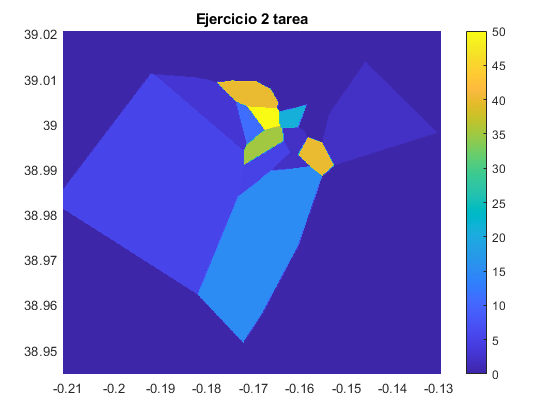

 
%cosa.saveFig()

% plot(Z_corrector)
title('Ejercicio 2 tarea')


% figure, [C,h]=contour(X1,Y1,LDEN_corrector, 30); clabel(C,h),colorbar
% title('Curvas de nivel tarea 2')
%writematrix(Z_corrector,'result.txt','Delimiter',',')  

